# Estimación de parámetros hidráulicos

I. Santos-Ruiz & F.R. López-Estrada

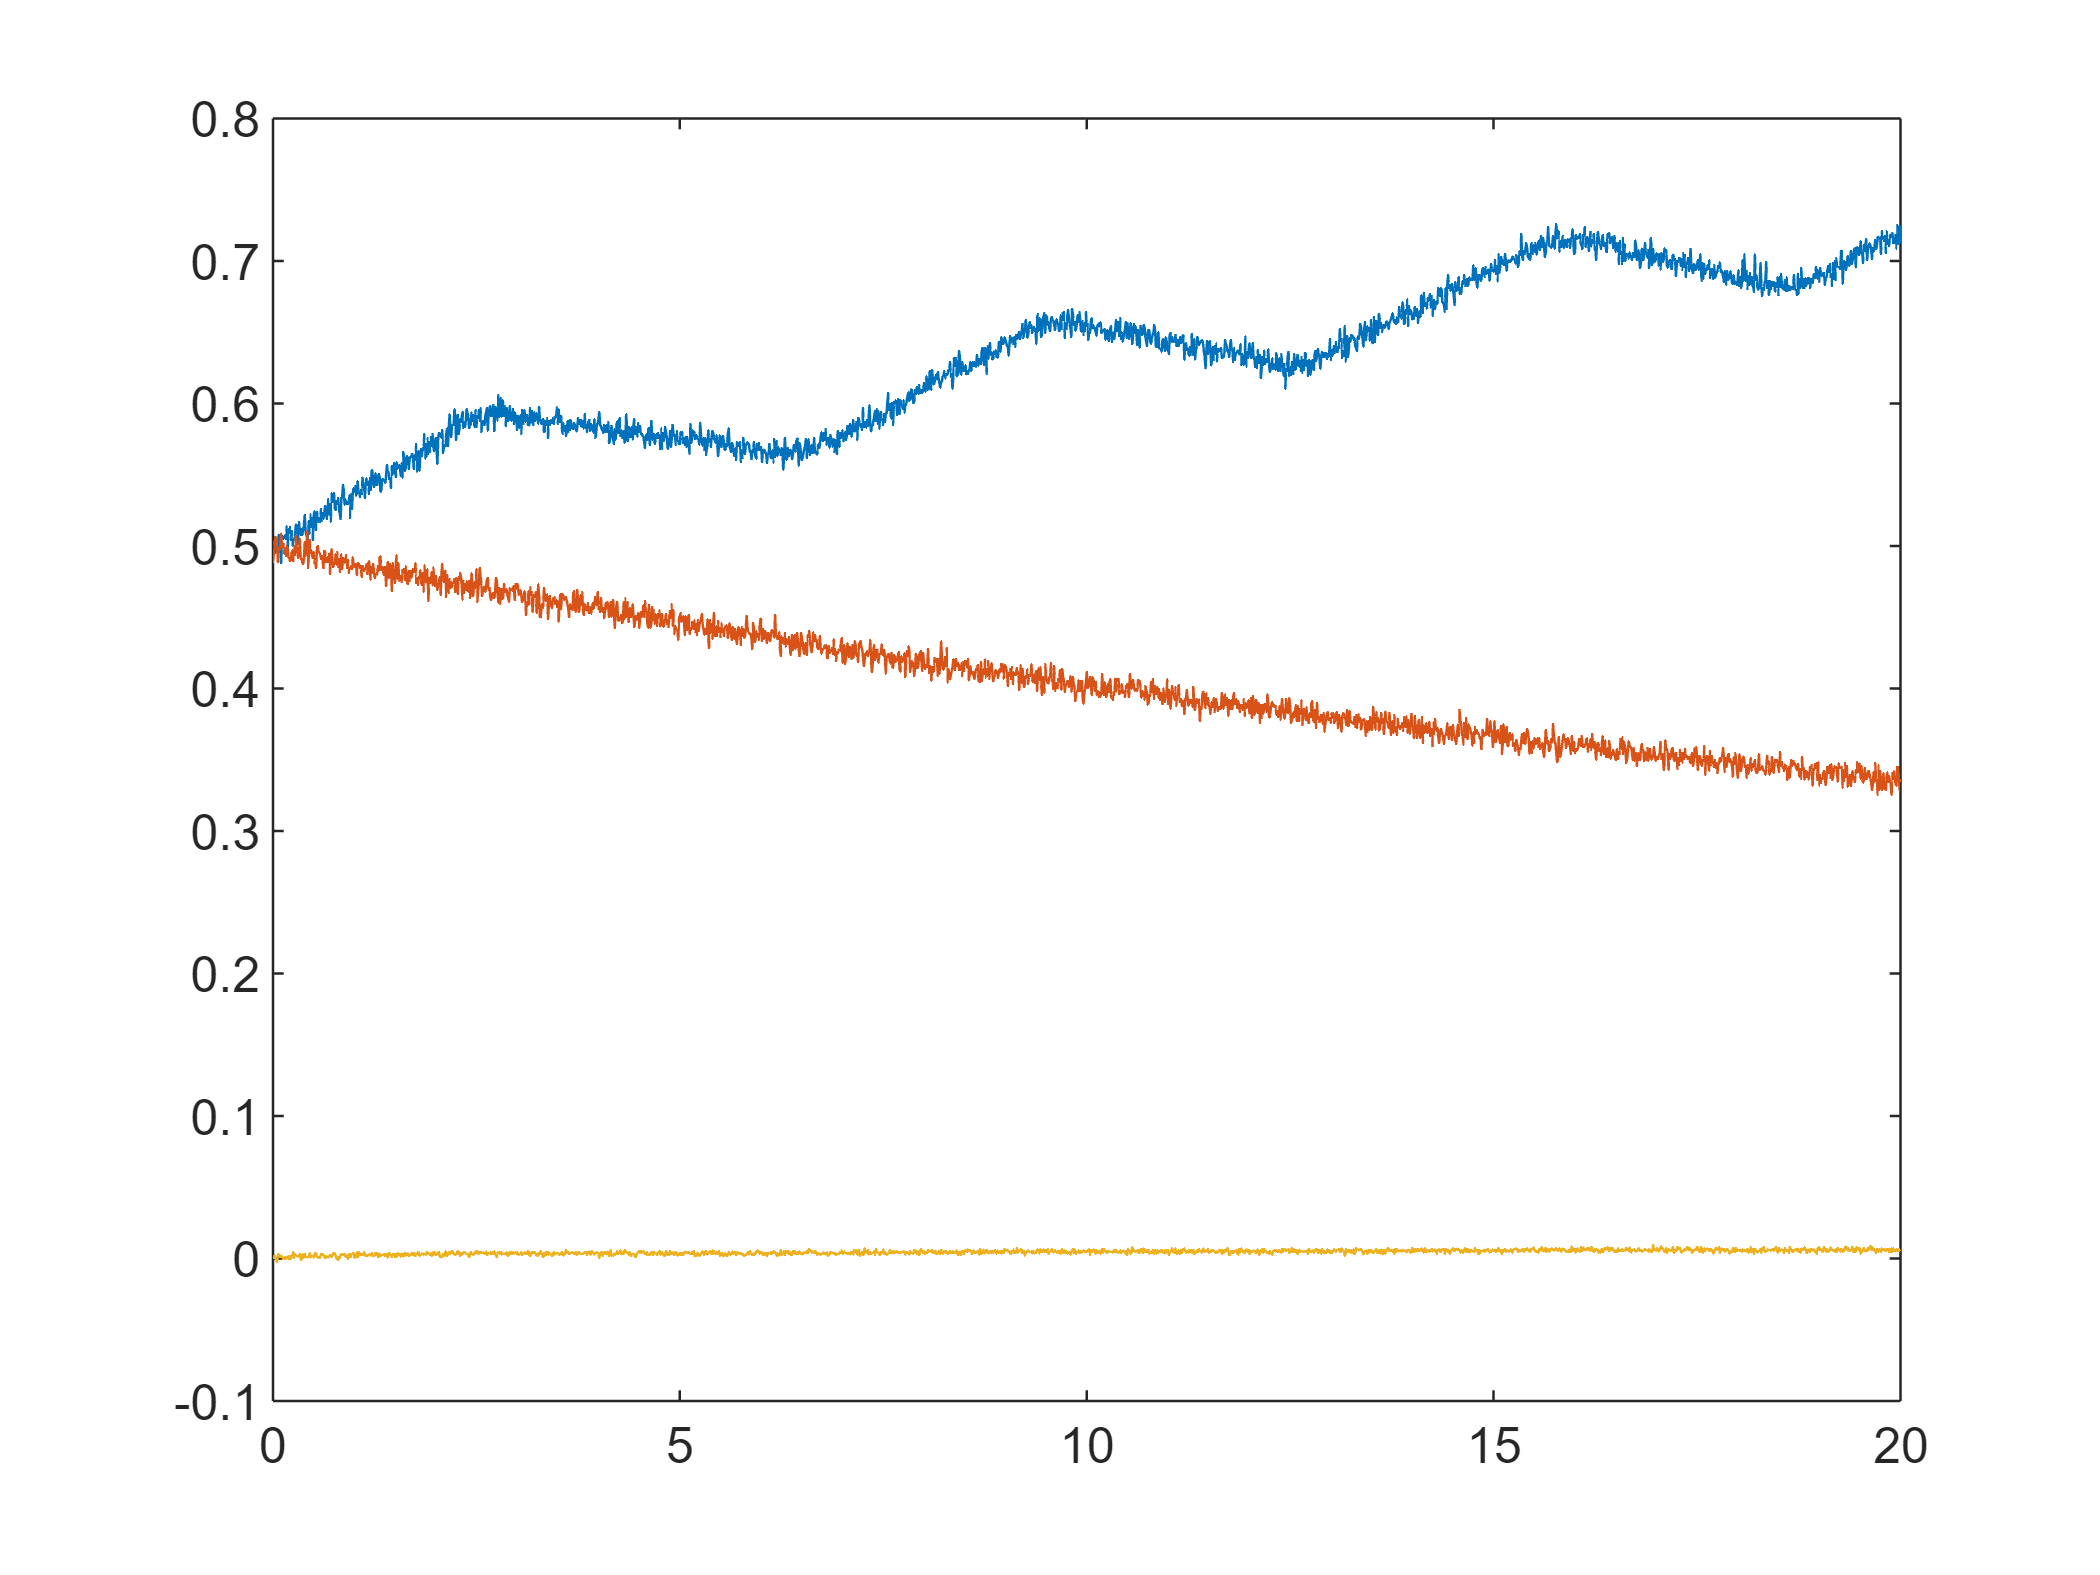

A1 = 0.5; A2 = 1; b1 = 0.01; b2 = 0.02; Ts = 0.01;
u = @(t) 1e-2*(1+square(t)); % patrón de flujo de entrada
q = @(b,h1,h2) b*sign(h1-h2).*sqrt(abs(h1-h2));
xprima = @(t,x) [1/A1*u(t)-1/A1*q(b1,x(1),x(2));
    1/A2*q(b1,x(1),x(2))-1/A2*q(b2,x(2),0)];
[t,x] = ode45(xprima,0:Ts:20,[0.5;0.5]);
y = [x,q(b1,x(:,1),x(:,2))];
y(:,1) = y(:,1) + 0.005*randn(size(y(:,1)));
y(:,2) = y(:,2) + 0.005*randn(size(y(:,2)));
y(:,3) = y(:,3) + 0.001*randn(size(y(:,3)));
figure(1); plot(t,y)

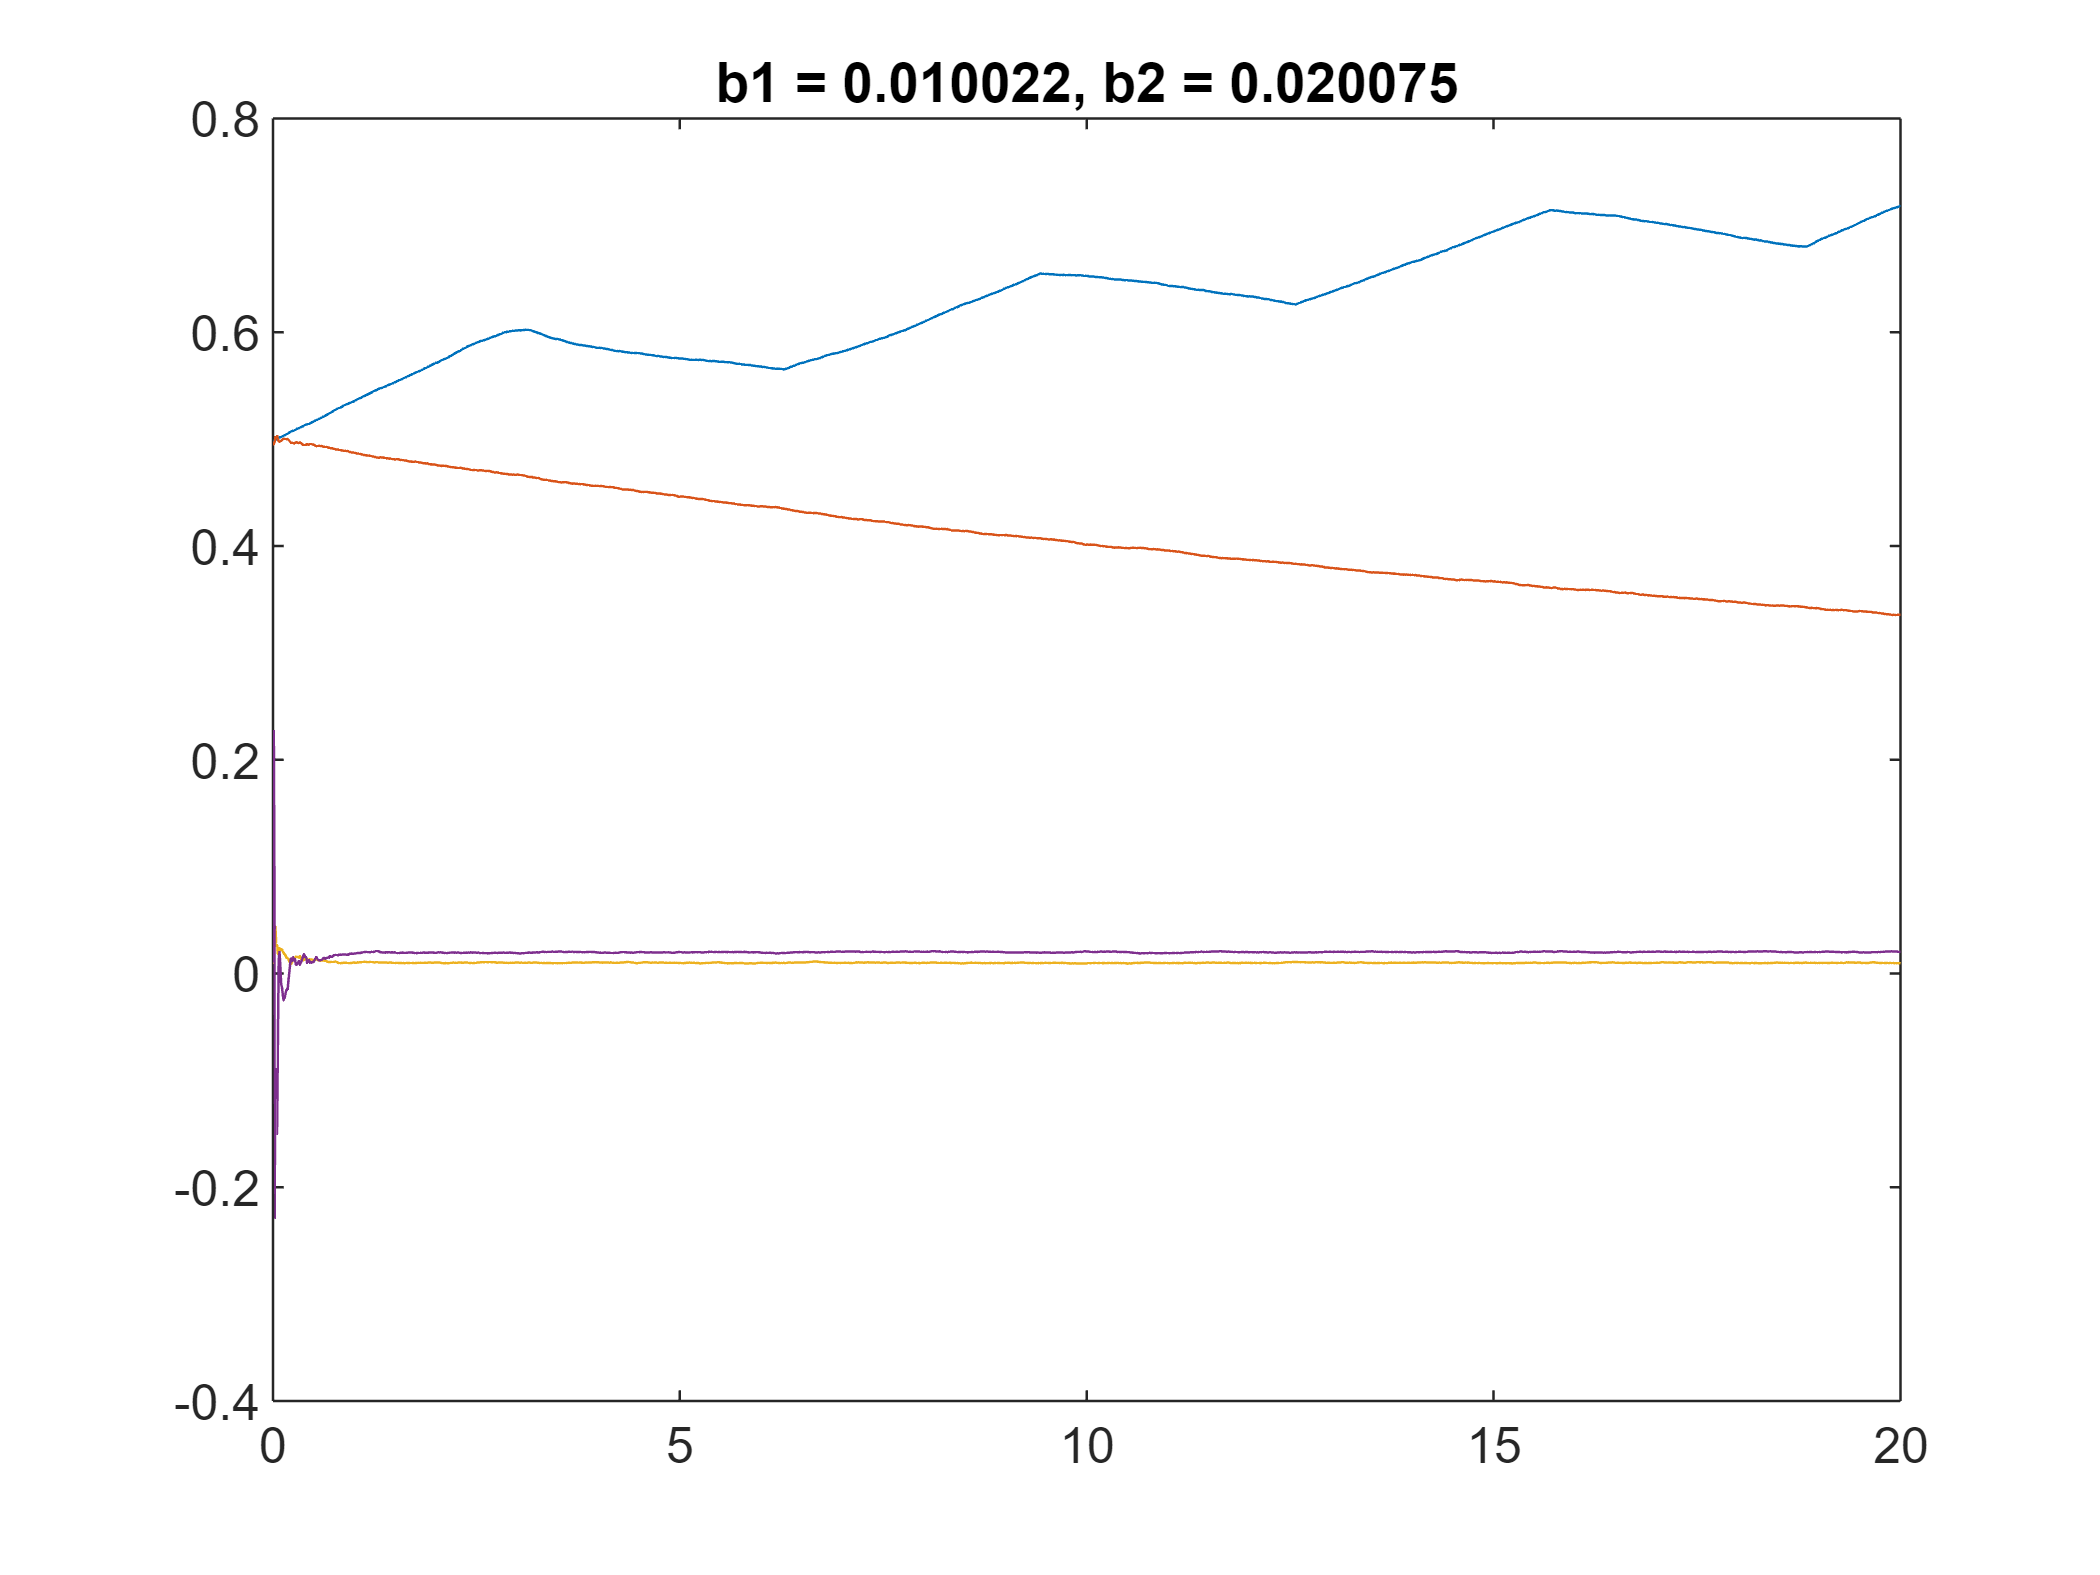

% exportgraphics(gcf,"tanques1.pdf","ContentType","vector","BackgroundColor","none")
f = @(x,u) [1/A1*u-1/A1*q(x(3),x(1),x(2));
    1/A2*q(x(3),x(1),x(2))-1/A2*q(x(4),x(2),0);0;0];
funTran = @(x,u) x + Ts*f(x,u);
funMeas = @(x,u) [x(1);x(2);q(x(3),x(1),x(2))];
ekf = extendedKalmanFilter(funTran,funMeas,[0.5;0.5;0.01;0.01]);
ekf.ProcessNoise = 1e-8;
ekf.MeasurementNoise = diag([0.005,0.005,0.001].^2);
uu = u(t);
xhat = zeros(4,numel(t));
for k = 1:numel(t)
    ekf.correct(y(k,:)',uu(k));
    xhat(:,k) = ekf.State;
    ekf.predict(uu(k));
end
figure(2); plot(t,xhat)
b1est = mean(xhat(3,(end+1)/2:end));
b2est = mean(xhat(4,(end+1)/2:end));
title("b1 = " + b1est + ", b2 = " + b2est)

% exportgraphics(gcf,"tanques2.pdf","ContentType","vector","BackgroundColor","none")